clear all
close all


## Load Dataset

load fisheriris
rng(1);

X = meas(:,1:4);
Y = [];%zeros(150,1);
for i=1:150
    y = species{i};
    Y=[Y string(y)];
end
Y = categorical(Y);

[m,n] = size(X) ;
P = 0.70 ;
idx = randperm(m) ;
trainx = X(idx(1:round(P*m)),:) ; 
trainy = Y(idx(1:round(P*m)));
testx = X(idx(round(P*m)+1:end),:) ;
testy = Y(idx(round(P*m)+1:end));

% colmin = min(trainx);
% colmax = max(trainx);
% trainx = rescale(trainx,"InputMin",colmin,"InputMax",colmax);
% colmin = min(testx);
% colmax = max(testx);
% testx = rescale(testx,"InputMin",colmin,"InputMax",colmax);

inputSize = size(trainx,2);
numClasses = 3;

## Build NN

layers = [
    featureInputLayer(inputSize,Normalization="rescale-zero-one")
    PQCLayer4
    fullyConnectedLayer(numClasses)
    softmaxLayer];


options = trainingOptions("sgdm", ...
    MiniBatchSize=20, ...
    InitialLearnRate=0.1, ...
    Momentum=0.9, ...
    ExecutionEnvironment="cpu", ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## Train NN

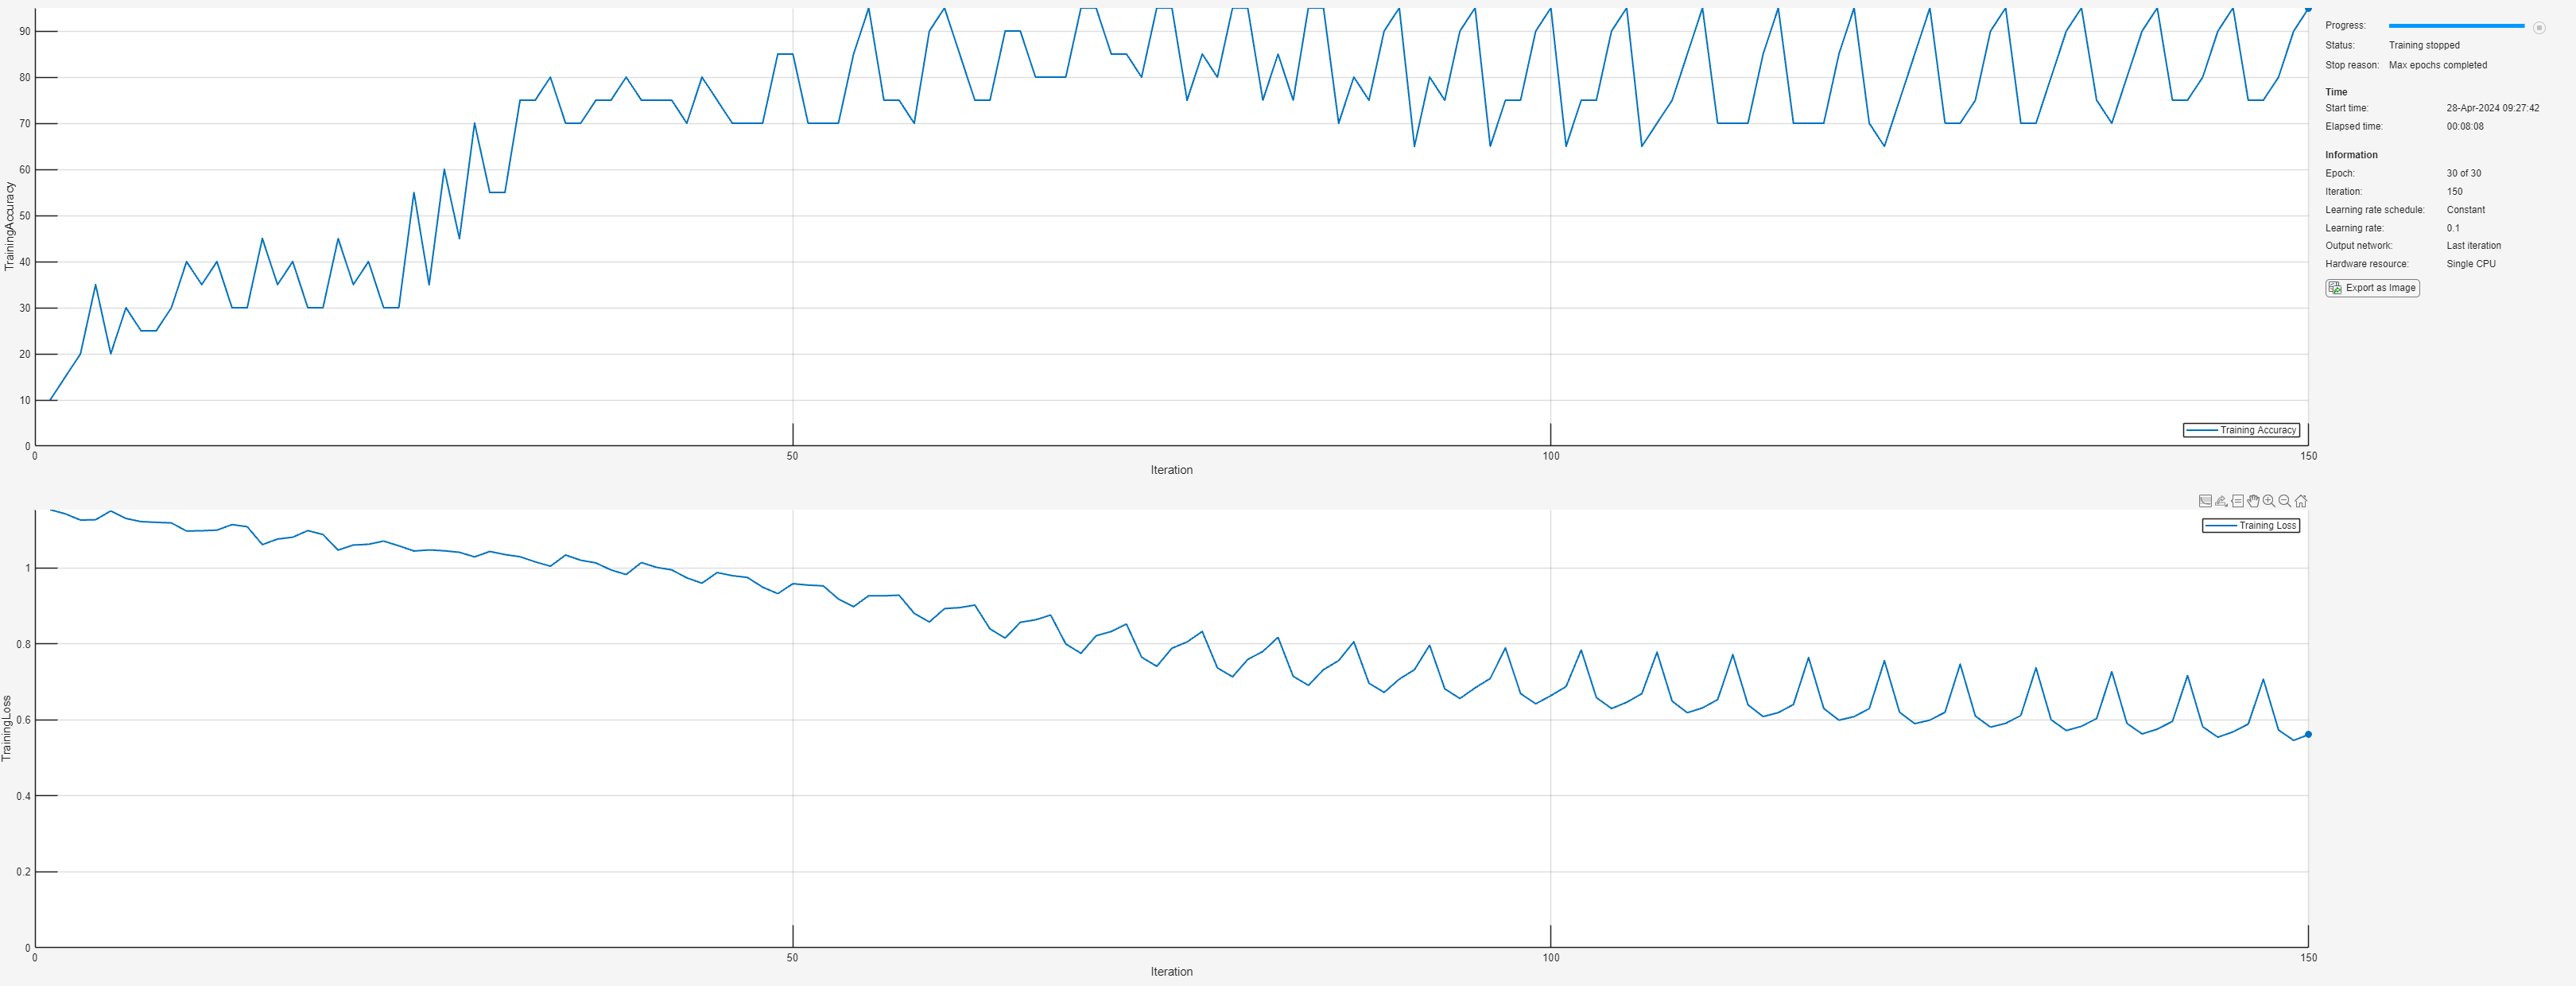

net = trainnet(trainx,trainy',layers,"crossentropy",options);

## Test

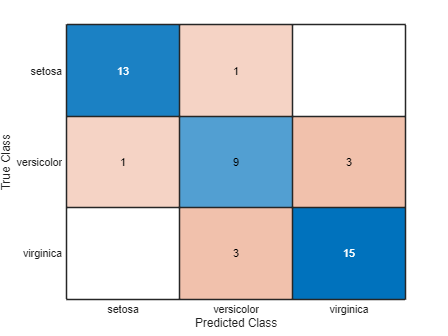

TTest = predict(net,testx);
classNames = ["setosa" "versicolor" "virginica"];
predictedLabels = onehotdecode(TTest,classNames,2);
confusionchart(testy,predictedLabels)

accuracy = mean(testy'==predictedLabels)

accuracy = 0.8222